## **Covid Detection Transfer Learning (densenet201)**

## Load Data 

% Data splits provided by the UCSD data github.
imdsTest = imageDatastore(fullfile('COVID19_CT_seg_20cases', 'test'),'IncludeSubfolders',true,'LabelSource','foldernames');
imdsTrain = imageDatastore(fullfile('../ucsd_dataset'),'IncludeSubfolders',true,'LabelSource','foldernames');

## Load Pretrained Network

net = shufflenet;

Use `analyzeNetwork` to display an interactive visualization of the network architecture and detailed information about the network layers.

% analyzeNetwork(net);

net.Layers(1);
inputSize = net.Layers(1).InputSize;

## Replace Final Layers

Extract the layer graph from the trained network. If the network is a `SeriesNetwork` object, such as AlexNet, VGG-16, or VGG-19, then convert the list of layers in `net.Layers` to a layer graph.

if isa(net,'SeriesNetwork') 
  lgraph = layerGraph(net.Layers); 
else
  lgraph = layerGraph(net);
end 

Find the names of the two layers to replace. You can do this manually or you can use the supporting function [findLayersToReplace](matlab:edit(fullfile(matlabroot,'examples','nnet','main','findLayersToReplace.m'))) to find these layers automatically. 

[learnableLayer,classLayer] = findLayersToReplace(lgraph);
[learnableLayer,classLayer];

In most networks, the last layer with learnable weights is a fully connected layer. Replace this fully connected layer with a new fully connected layer with the number of outputs equal to the number of classes in the new data set (5, in this example). In some networks, such as SqueezeNet, the last learnable layer is a 1-by-1 convolutional layer instead. In this case, replace the convolutional layer with a new convolutional layer with the number of filters equal to the number of classes. To learn faster in the new layer than in the transferred layers, increase the learning rate factors of the layer.

numClasses = numel(categories(imdsTrain.Labels));

if isa(learnableLayer,'nnet.cnn.layer.FullyConnectedLayer')
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
    
elseif isa(learnableLayer,'nnet.cnn.layer.Convolution2DLayer')
    newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
end

lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);

The classification layer specifies the output classes of the network. Replace the classification layer with a new one without class labels. `trainNetwork` automatically sets the output classes of the layer at training time. 

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);

## Freeze Initial Layers

layers = lgraph.Layers;
connections = lgraph.Connections;

frozen = 50;
layers(1:frozen) = freezeWeights(layers(1:frozen));
lgraph = createLgraphUsingConnections(layers,connections);

## Train Network

% Augment data to fit new network
augimdsTrain = augmentedImageDatastore(inputSize,imdsTrain,"ColorPreprocessing","gray2rgb");
augimdsTest = augmentedImageDatastore(inputSize,imdsTest,"ColorPreprocessing","gray2rgb");


Specify the training options.

trainingOptions('sgdm', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',5, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'Verbose',false);

## Train the network using the training data.

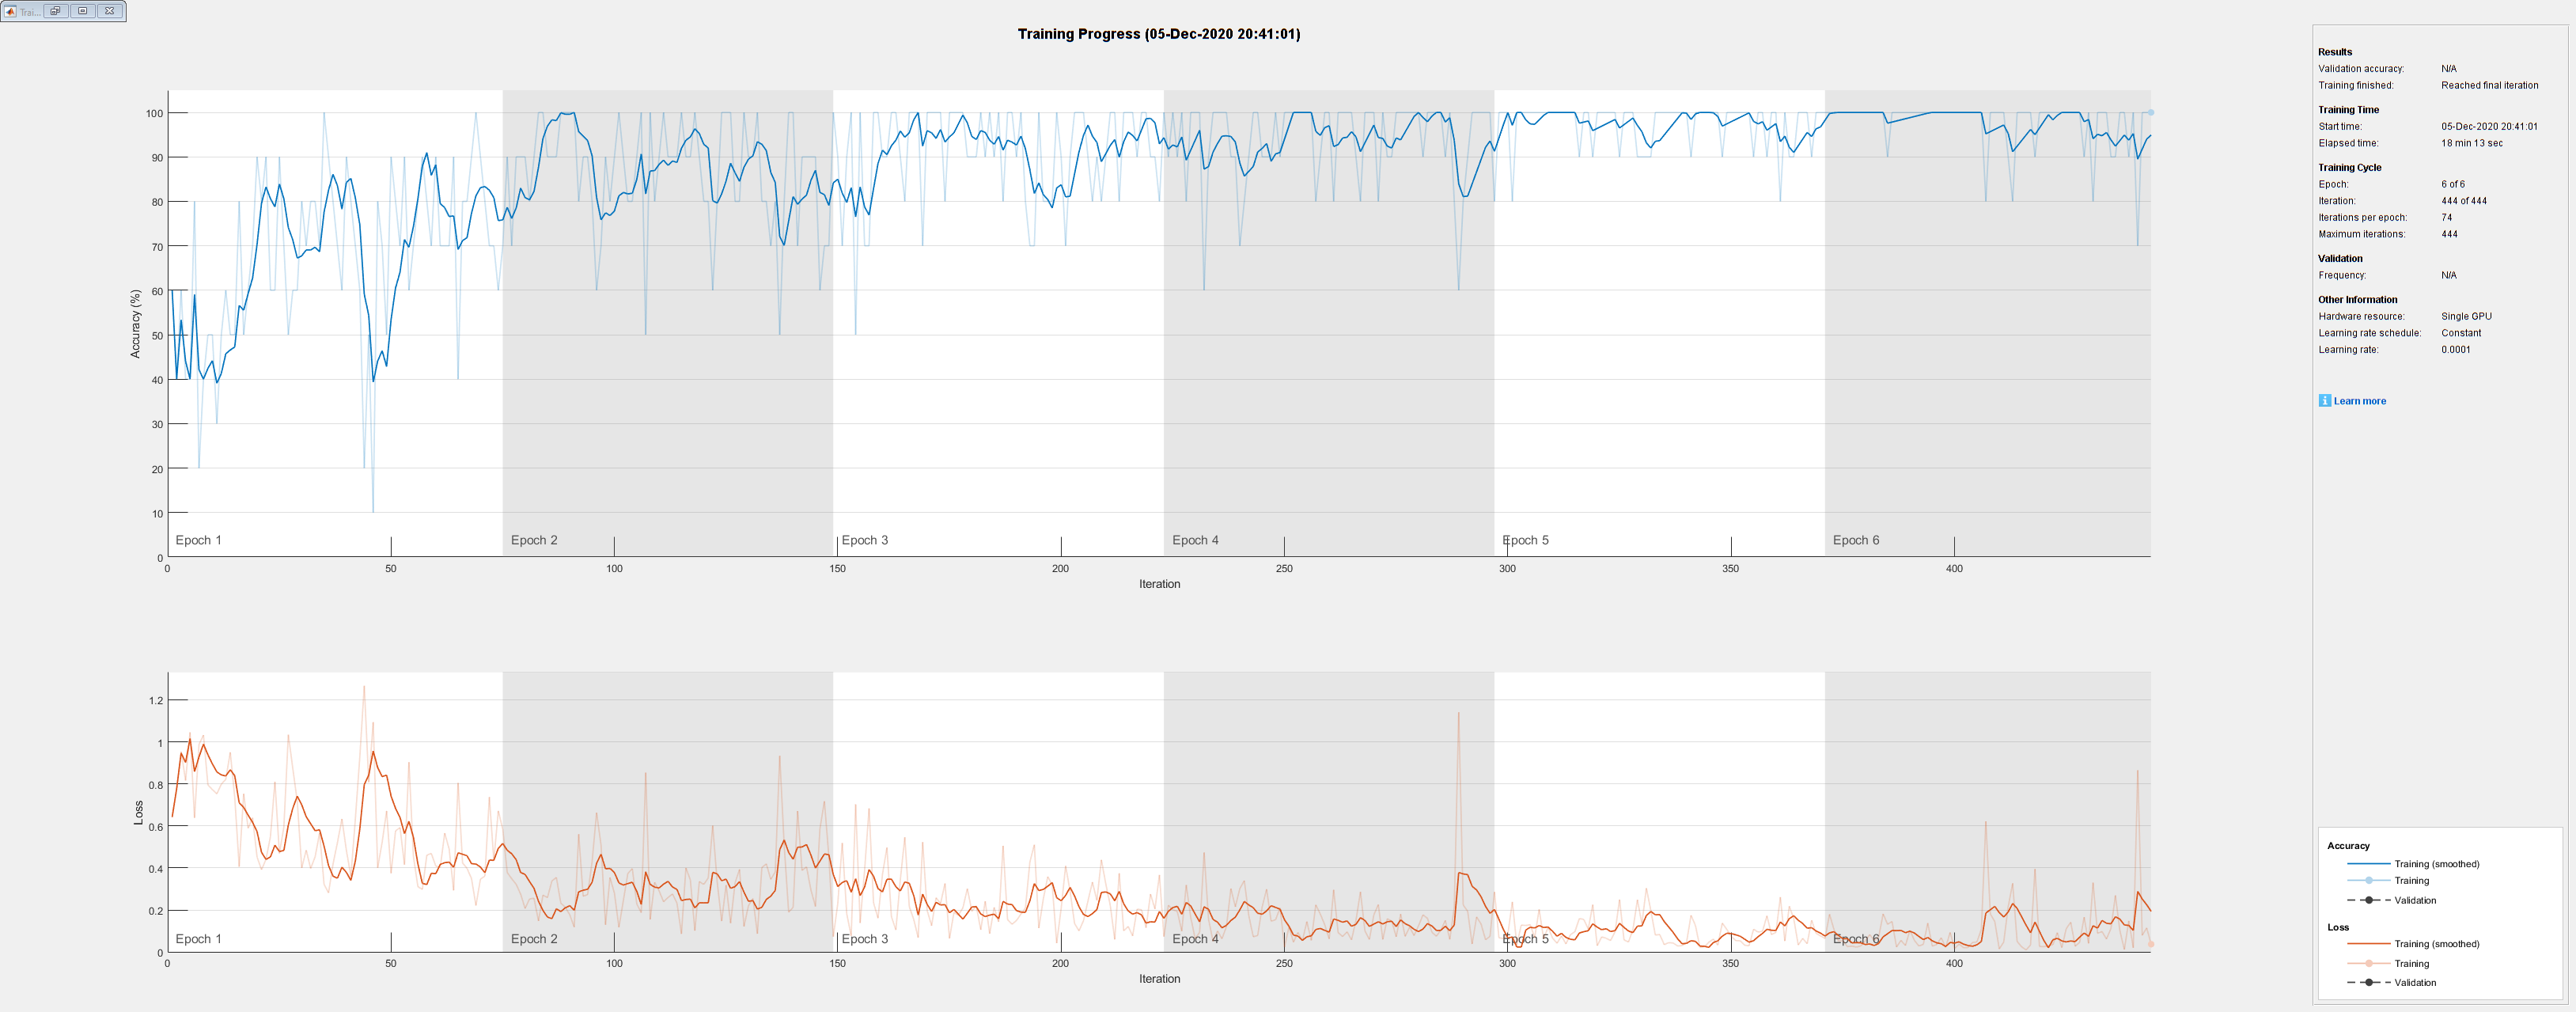

net = trainNetwork(augimdsTrain,lgraph,options);

## Classify Test Images

Classify the test images using the fine-tuned network, and calculate the test accuracy.

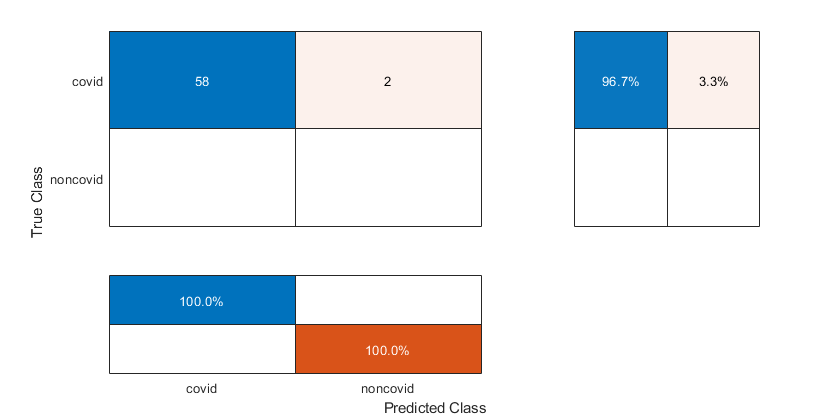

[YPred,probs] = classify(net,augimdsTest);

% Get number of images.
numImages = size(YPred,1);
avg_accs = zeros([0,2]);
% Index tracker.
total_idx = 1;
for i = 1:numImages/3
    % Reset sums.
    covidSum = 0;
    noncovidSum = 0;
    % Get the sum of the patient's probability of covid and noncovid
    for j = 1:3
        covidSum = covidSum + probs(total_idx,1);
        noncovidSum = noncovidSum + probs(total_idx,2);
        total_idx = total_idx + 1;
    end
    avg_accs(i,1) = round(covidSum/3,4);
    avg_accs(i,2) = round(noncovidSum/3,4);
end

for i = 1:numImages/3
    % Print patient info and results
    if(i < 10)
        fprintf('Patient %d >> Avg COVID Probability = %.4f\n',i,avg_accs(i,1));
        fprintf('\t\t\t Avg nonCOVID Probability = %.4f\n',avg_accs(i,2));
    else
                fprintf('Patient %d >> Avg COVID Probability = %.4f\n',i,avg_accs(i,1));
        fprintf('\t\t\t  Avg nonCOVID Probability = %.4f\n',avg_accs(i,2));
    end
end

% Extract the class labels from the test data.
YTest = imdsTest.Labels;

accuracy = mean(YPred == YTest);

% Calculate Average F-score.
s = max(size(unique(YTest)));
conf_values = confusionmat(YTest, YPred);
tp_m = diag(conf_values); 
for i = 1:s
   % Get true positive, false negative, false positive
    TP = conf_values(1,1);
    FN = conf_values(1,2);
    FP = conf_values(2,1);
    TN = conf_values(2,2);
    
    % Calculate Recall, precision, fscore
    Recall = TP /(TP + FN);
    if isnan(Recall)
        Recall = 0;
    end
    % Calculate Precision
    Precision = TP / (TP + FP);
    if isnan(Precision)
        Precision = 0;
    end
    % Calculate FScore
    FScore = (2*(Precision * Recall)) / (Precision+Recall);
    if isnan(FScore)
        FScore = 0;
    end
end
avg_f_score = mean(fscore(:));

% Display confusion chart.
fig = figure;
conf = confusionchart(YTest, YPred,'RowSummary','row-normalized','ColumnSummary','column-normalized');
fig_Position = fig.Position;
fig_Position(3) = fig_Position(3)*1.5;
fig.Position = fig_Position;

accuracy

accuracy = 0.9667

fscore

fscore = 0.9831

Display four sample validation images with predicted labels and the predicted probabilities of the images having those labels. With Actiavation Heatmaps

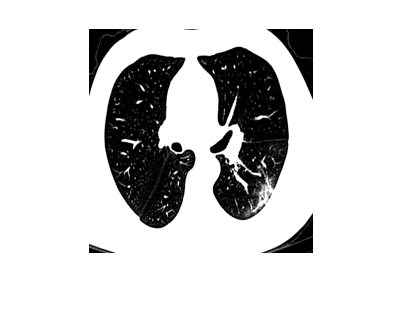

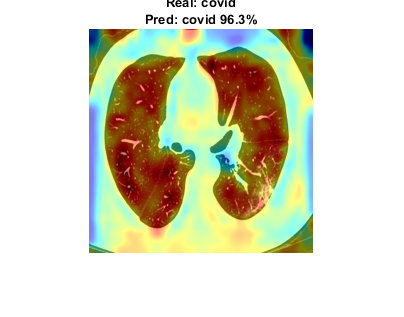

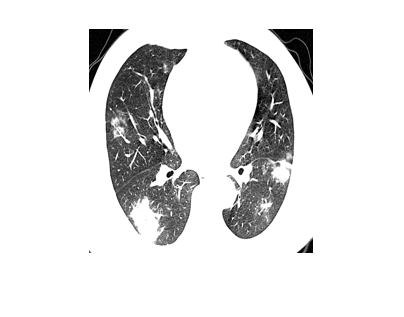

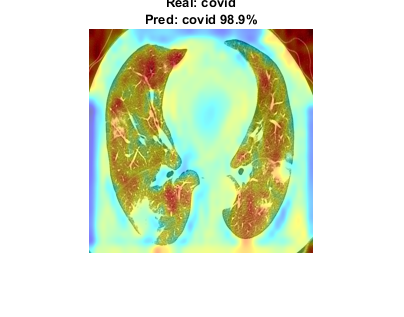

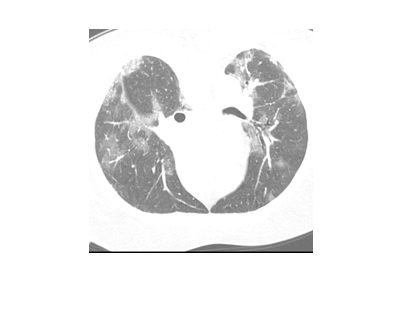

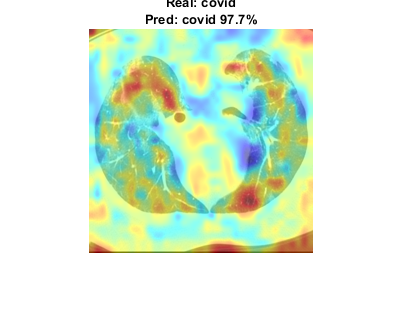

idx = randperm(numel(imdsTest.Files),3);
figure
for i = 1:3 
    I = readimage(imdsTest,idx(i));
    actlabel = YTest(idx(i));
    predlabel = YPred(idx(i));
    

    % Activation Map
    featureLayerName = "node_199";
    softmaxName = "node_203";
    
    resizeI = imresize(I,inputSize(1:2));
    
    imageActivations = activations(net,imResized,featureLayerName);
    
    [classfn,score] = classify(net,resizeI);
    
    % To use Grad-CAM, create a dlnetwork from the GoogLeNet network. First, create a layer graph from the network.
    lgraph = layerGraph(net);
    % To access the data that uses for classification, remove its final classification layer.
    lgraph = removeLayers(lgraph, lgraph.Layers(end).Name);
    % Create a dlnetwork from the layer graph.
    dlnet = dlnetwork(lgraph);
    
    
    
    % To use automatic differentiation, convert the image to a dlarray.
    dlImg = dlarray(single(I),'SSC');
    
    % Compute the Grad-CAM gradient for the image by calling dlfeval on the gradcam function.
    [featureMap, dScoresdMap] = dlfeval(@gradcam, dlnet, dlImg, softmaxName, featureLayerName, classfn);
    
    % Resize the gradient map to the network's image size, and scale the scores to the appropriate levels for display.
    gradcamMap = sum(featureMap .* sum(dScoresdMap, [1 2]), 3);
    gradcamMap = extractdata(gradcamMap);
    gradcamMap = rescale(gradcamMap);
    gradcamMap = imresize(gradcamMap, inputSize(1:2), 'Method', 'bicubic');
    
    % Show the Grad-CAM levels on top of the image by using an 'AlphaData' value of 0.5. The 'jet' colormap has deep blue as the lowest value and deep red as the highest.
    figure;
    imshow(resizeI);
    
    figure;
    imshow(resizeI); % Show image pairs
    hold on;
    imagesc(gradcamMap,'AlphaData',0.5);
    colormap jet
    hold off;
    title({"Real: " + string(actlabel), "Pred: " + string(predlabel) + " " + ...
    num2str(100*max(probs(idx(i),:)),3) + "%"});
        
end

HELPER FUNCTIONS FOR CAM

function [featureMap,dScoresdMap] = gradcam(dlnet, dlImg, softmaxName, featureLayerName, classfn)
    [scores,featureMap] = predict(dlnet, dlImg, 'Outputs', {softmaxName, featureLayerName});
    classScore = scores(classfn);
    dScoresdMap = dlgradient(classScore,featureMap);
end